## **ABORDAGEM EM ESPAÇOS DE ESTADOS**

%% LIMPEZA DO SISTEMA
clc; clear; close all;

% PROCESSO
s = tf('s');
Ts_ss = 20

Ts_ss = 20


%% 1. Parâmetros e Modelos da Planta (FBC - Malha de Potência G11(s))
disp('1. Definindo parâmetros da planta FBC conforme o artigo...');

1. Definindo parâmetros da planta FBC conforme o artigo...


Kp = 5.88;   % Ganho da planta
Tp = 125;   % Constante de tempo da planta [s]
ORD = 5;   % Ordem da planta

N = 20;
Nu = 2;
R = 1*eye(Nu);

P = Kp/(Tp*s+1)^ORD

P =
 
                                 5.88
  -------------------------------------------------------------------
  3.052e10 s^5 + 1.221e09 s^4 + 1.953e07 s^3 + 156250 s^2 + 625 s + 1
 
Continuous-time transfer function.



P_d = c2d(P, Ts_ss)

P_d =
 
  4.498e-06 z^4 + 0.0001024 z^3 + 0.0002275 z^2 + 7.843e-05 z + 2.639e-06
  -----------------------------------------------------------------------
        z^5 - 4.261 z^4 + 7.261 z^3 - 6.188 z^2 + 2.636 z - 0.4493
 
Sample time: 20 seconds
Discrete-time transfer function.



[B, A] = tfdata(P_d, 'v')

B = 	1.0e+-3 *

         0    0.0045    0.1024    0.2275    0.0784    0.0026


A =     1.0000   -4.2607    7.2615   -6.1878    2.6365   -0.4493


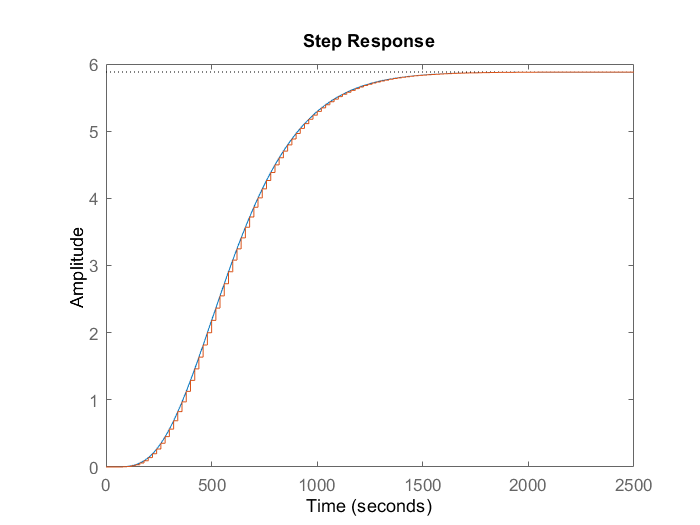


%[B, A] = tfdata(G, 'v');

figure
step(P)
hold on
step(P_d)


p = -0.5

p = -0.5000

temp = [1 p];
for i=1:ORD
    temp = conv([1 p], temp);
end

C = [];
H = [1 zeros(1,ORD)];
for i=2:ORD+2
    C = [C temp(i)];
end

delta = [1 -1];
At = conv(delta,A);                         % CALCULA Ã

an = length(A); 




A_ss = [-At(1,2:end)' eye(an, an - 1)];      % MATRIZ DO SISTEMA
D = (C - At(1,2:end))';

% =============| INICIALIZA AS MATRIZES DE ITERAÇÃO |=========
Ga = [];
F =  [];
E =  [];

%============| ITERAÇÃO PRA OBTER O ESTADO FUTURO |===========
for i = 0:N-1
    Ga = [Ga H*A_ss^i*B'];
    F = [F; H*A_ss^(i+1)];
    E = [E; H*A_ss^i*D];
end

% =====================| MATRIZ DINAMICA |====================
G = zeros(N);
for n = 1:N
    G(n:N, n) = Ga(1:N-n+1);
end

disp(G)

  Columns 1 through 13

         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0000         0         0         0         0         0         0         0         0         0         0         0         0
    0.0001    0.0000         0         0         0         0         0         0         0         0         0         0         0
    0.0008    0.0001    0.0000         0         0         0         0         0         0         0         0         0         0
    0.0031    0.0008    0.0001    0.0000         0         0         0         0         0         0         0         0         0
    0.0083    0.0031    0.0008    0.0001    0.0000         0         0         0         0         0         0         0         0
    0.0181    0.0083    0.0031    0.0008    0.0001    0.0000         0         0         0         0         0         0         0
    0.0344    0.0181    0.0083    0.0031    0.0008    0.000


% ======================| OTIMIZAÇÃO |========================
% K = (G'*G + R)\G';
% 
% Kr_ss = sum(K(1,:))
% KE_ss = K(1,:)*E
% KF_ss = K(1,:)*F


%% OTIMIZAÇÃO PARA Nu < N
G_trunc = G(:, 1:Nu);           
K = (G_trunc' * G_trunc + R) \ G_trunc';

Kr_ss = sum(K(1,:));            % Ganho sobre referência
KE_ss = K(1,:) * E;             % Ganho sobre perturbação
KF_ss = K(1,:) * F;             % Ganho sobre estados

eig(A_ss-B'*KF_ss)

ans =    0.8911 + 0.1866i
   0.8911 - 0.1866i
   0.7708 + 0.1053i
   0.7708 - 0.1053i
   0.7287 + 0.0000i
   0.5923 + 0.0000i


eig(A_ss-D*H)

ans =    0.5017 + 0.0000i
   0.5009 + 0.0015i
   0.5009 - 0.0015i
   0.4991 + 0.0015i
   0.4991 - 0.0015i
   0.4983 + 0.0000i



% %% ========================================================================
% % ANÁLISE DE ROBUSTEZ
% % =========================================================================
% c2 = P; c1 = c2;
% DT_modelo = 0;                  % Atraso nominal (será tratado separadamente)
% DT_incerteza = 0;               % Atraso adicional para teste
% 
% % 1. Definição da faixa de frequência para análise
% w = logspace(-2, log10(pi/Ts_ss), 500);
% 
% % 2. Modelo da Incerteza Multiplicativa
% % Usa a variável de incerteza para o teste
% delta_P_num = [1 zeros(1, DT_incerteza-1) -1];
% delta_P_den = [1 zeros(1, DT_incerteza)];
% delta_P = tf(delta_P_num, delta_P_den, Ts_ss);
% mag_delta_P = squeeze(abs(freqresp(delta_P, w)));
% 
% % 3. Cálculo do Índice de Robustez usando o MODELO CORRETO
% % Cria a FT do filtro C(z) dinamicamente
% C_tf = tf([1 c1 c2], 1, Ts_ss);
% 
% % ** CORREÇÃO FUNDAMENTAL: Cria a FT da planta GPC (b/At) para a análise **
% P_gpc = tf([0 B], At, Ts_ss); % Note o uso de 'At' no denominador
% 
% % Calcula a função de transferência de malha L(z) = C(z)*P_GPC(z)
% L = C_tf * P_gpc; 
% 
% % Calcula a magnitude do índice de robustez
% Ir_freqresp = (1 + freqresp(L, w)) ./ freqresp(L, w);
% mag_Ir = squeeze(abs(Ir_freqresp));
% 
% % 4. Plot dos resultados
% figure;
% loglog(w, mag_delta_P, 'k-', 'LineWidth', 2);
% hold on;
% loglog(w, mag_Ir, 'r--', 'LineWidth', 2.5);
% hold off;
% 
% title_str = sprintf('Análise de Robustez com C(z) = 1 + (%.2f)z^{-1} + (%.2f)z^{-2}', c1, c2);
% title(title_str, 'FontSize', 12);
% xlabel('Frequência (rad/s)', 'FontSize', 11);
% ylabel('Magnitude', 'FontSize', 11);
% legend('|δP(jω)| (Incerteza)', '|I_r(\omega)| (Índice de Robustez)', 'Location', 'southwest');
% grid on;
% ylim([1e-2 1e2]);


## **MADRC**

%% Script para Configuração da Simulação do Controlador MADRC (Modelo COMPLETO)
%clear; clc; close all;

% Período de amostragem [s]
Ts = 1;


% Coeficientes para a PLANTA REAL (5ª ordem) -> G_planta = K / (T*s + 1)^5
numerador_real = Kp;
den_poly = [Tp 1];
denominador_real = conv(den_poly, conv(den_poly, conv(den_poly, conv(den_poly, den_poly))));

% Coeficientes para o COMPENSADOR INTERNO (3ª ordem) -> Gcp = 1 / (T*s + 1)^3
numerador_gcp = 1;
den_poly_gcp = [Tp 1];
denominador_gcp = conv(den_poly_gcp, conv(den_poly_gcp, den_poly_gcp));

%[numerador_gcp, denominador_gcp] = tfdata(c2d(tf(numerador_gcp,denominador_gcp),Ts), 'v');

disp('----------------------------------------------------');

----------------------------------------------------


disp('Simulando o sistema COMPLETO:');

Simulando o sistema COMPLETO:


disp('Planta no modelo principal: 5ª Ordem');

Planta no modelo principal: 5ª Ordem


disp('Compensador dentro do controlador: 3ª Ordem');

Compensador dentro do controlador: 3ª Ordem


disp('----------------------------------------------------');

----------------------------------------------------



%% 2. Parâmetros do Controlador MADRC
disp('2. Usando os parâmetros de sintonia ORIGINAIS da Tabela 10 do artigo...');

2. Usando os parâmetros de sintonia ORIGINAIS da Tabela 10 do artigo...



% Parâmetros de sintonia da Tabela 10 para o "Controller 1"
omega_c = 0.01;
omega_o = 0.1;
b0 = 0.0005;

% Ganhos do Controlador (SFCL) baseados em omega_c
kp = omega_c^2;
kd = 2 * omega_c;

% Ganhos do Observador (ESO) baseados em omega_o
beta1 = 3 * omega_o;
beta2 = 3 * omega_o^2;
beta3 = omega_o^3;

disp(['omega_c = ' num2str(omega_c)]);

omega_c = 0.01


disp(['omega_o = ' num2str(omega_o)]);

omega_o = 0.1


disp(['b0 = ' num2str(b0)]);

b0 = 0.0005



%% 3. Parâmetros da Simulação
disp('3. Definindo parâmetros da simulação...');

3. Definindo parâmetros da simulação...


T_sim = 8000;
ref_inicial = 0;
ref_final = 1;
t_degrau = 100;

disp('Configuração concluída. Execute o modelo Simulink atualizado.');

Configuração concluída. Execute o modelo Simulink atualizado.
